# FNN CNN LSTM - Test

%clear

## 저장된 데이타를 모두 읽어들인다.

%{
load data_05 
load data_06 
load data_07 
load data_0506 
load data_0606 
load data_05plus06      
load data_05plus07      
load data_06plus07      
load data_05plus06plus07

load cap_05             
load cap_06             
load cap_07             
load cap_0506           
load cap_0605           
load cap_05plus06       
load cap_05plus07       
load cap_06plus07       
load cap_05plus06plus07 


load charVIT_05
load charVIT_06
load charVIT_07
load charVIT_0506              
load charVIT_0605              
load charVIT_05plus06          
load charVIT_05plus07          
load charVIT_06plus07          
load charVIT_05plus06plus07    

load InitC_05 				
load InitC_06 				
load InitC_07 				
load InitC_0506 			
load InitC_0605 			
load InitC_05plus06 		
load InitC_05plus07 		
load InitC_06plus07 		
load InitC_05plus06plus07 	

load charVIT_input_size                  
load charVIT_05plus06_input_size         
load charVIT_05plus07_input_size         
load charVIT_06plus07_input_size         
load charVIT_05plus06plus07_input_size  

load xB_gen_05 yB_gen_05 ym_gen_05 yr_gen_05
load xB_gen_06 yB_gen_06 ym_gen_06 yr_gen_06
load xB_gen_07 yB_gen_07 ym_gen_07 yr_gen_07

%}

load xB_05 yB_05 ym_05 yr_05
load xB_06 yB_06 ym_06 yr_06
load xB_07 yB_07 ym_07 yr_07
load xB_0506 yB_0506 ym_0506 yr_0506
load xB_0605 yB_0605 ym_0605 yr_0605
load xB_05plus06 yB_05plus06 ym_05plus06 yr_05plus06
load xB_05plus07 yB_05plus07 ym_05plus07 yr_05plus07
load xB_06plus07 yB_06plus07 ym_06plus07 yr_06plus07
load xB_05plus06plus07 yB_05plus06plus07 ym_05plus06plus07 yr_05plus06plus07


## Load model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

%{
load  netFNN40_0506_v1 
load  netCNN1_0506_v1 
load  netCNN2_0506_v1 
load  netLSTM_0506_v1 
load  netGRU_0506_v1 

load  netFNN40_0605_v1 
load  netCNN1_0605_v1 
load  netCNN2_0605_v1 
load  netLSTM_0605_v1 
load  netGRU_0605_v1 
%}



### Prediciton #5 by model #5 - Full Data

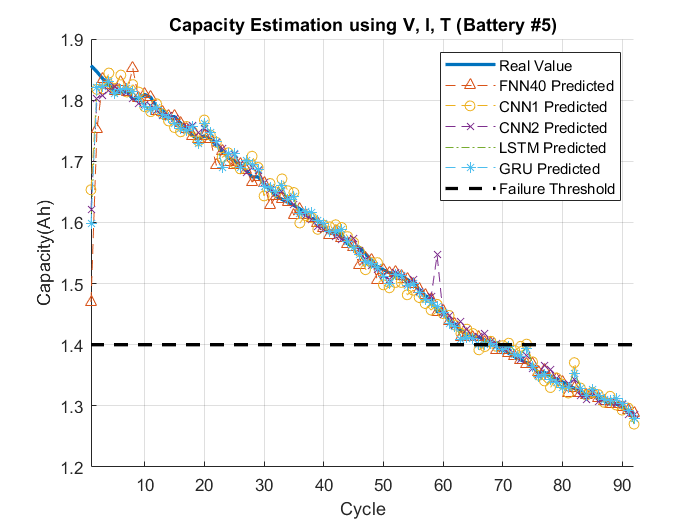

load  netFNN40_05_v1 
load  netCNN1_05_v1 
load  netCNN2_05_v1 
load  netLSTM_05_v1 
load  netGRU_05_v1 

BatteryNum = 5;
pFNN40_05 = netFNN40_05_v1(xB_05');
total_cycle = length(pFNN40_05);
cellx = num2cell(xB_05', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_05 = predict(netCNN1_05_v1, x_4d);
pCNN2_05 = predict(netCNN2_05_v1, x_4d);
pLSTM_05 = cell2mat(predict(netLSTM_05_v1, num2cell(xB_05', 1)));
pGRU_05 = cell2mat(predict(netGRU_05_v1, num2cell(xB_05', 1)));

y_05 = yB_05*yr_05 + ym_05;
pFNN40_05 = pFNN40_05*yr_05 + ym_05;
pCNN1_05 = pCNN1_05*yr_05 + ym_05;
pCNN2_05 = pCNN2_05*yr_05 + ym_05;
pLSTM_05 = pLSTM_05*yr_05 + ym_05;
pGRU_05 = pGRU_05*yr_05 + ym_05;

figure, hold on, grid on,
plot(y_05, 'linewidth', 2), plot(pFNN40_05, '^--'), plot(pCNN1_05, 'o--'), plot(pCNN2_05, 'x--'), plot(pLSTM_05, '-.'),plot(pGRU_05, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_05 = sqrt(mean(( y_05' - pFNN40_05' ).^2))

rmse_pFNN40_05 = 0.0424

rmse_pCNN1_05  = sqrt(mean(( y_05' - pCNN1_05 ).^2))

rmse_pCNN1_05 = single
0.0259

rmse_pCNN2_05  = sqrt(mean(( y_05' - pCNN2_05 ).^2))

rmse_pCNN2_05 = single
0.0278

rmse_pLSTM_05  = sqrt(mean(( y_05' - pLSTM_05 ).^2))

rmse_pLSTM_05 = single
0.0289

rmse_pGRU_05   = sqrt(mean(( y_05' - pGRU_05  ).^2))

rmse_pGRU_05 = single
0.0288


rmse_pFNN40_05

rmse_pFNN40_05 = 0.0424

rmse_pCNN1_05 

rmse_pCNN1_05 = single
0.0259

rmse_pCNN2_05 

rmse_pCNN2_05 = single
0.0278

rmse_pLSTM_05 

rmse_pLSTM_05 = single
0.0289

rmse_pGRU_05  

rmse_pGRU_05 = single
0.0288

### Prediciton #6 by model #6 - Full Data

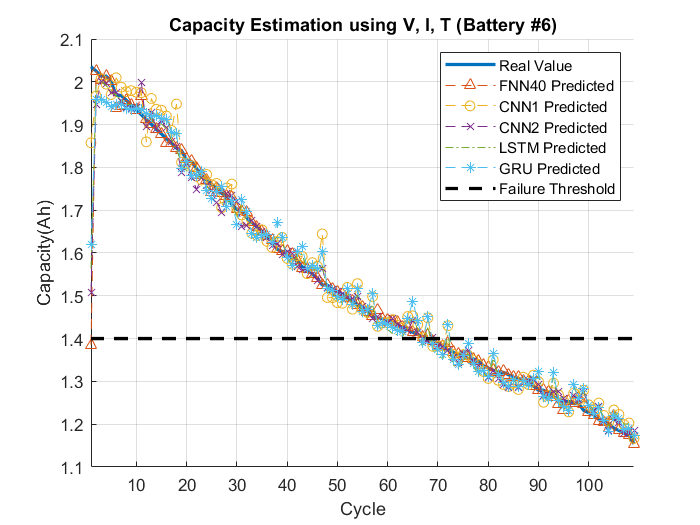

load  netFNN40_06_v1 
load  netCNN1_06_v1 
load  netCNN2_06_v1 
load  netLSTM_06_v1 
load  netGRU_06_v1 

BatteryNum = 6;
pFNN40_06 = netFNN40_06_v1(xB_06');
total_cycle = length(pFNN40_06);
cellx = num2cell(xB_06', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_06 = predict(netCNN1_06_v1, x_4d);
pCNN2_06 = predict(netCNN2_06_v1, x_4d);
pLSTM_06 = cell2mat(predict(netLSTM_06_v1, num2cell(xB_06', 1)));
pGRU_06 = cell2mat(predict(netGRU_06_v1, num2cell(xB_06', 1)));

y_06 = yB_06*yr_06 + ym_06;
pFNN40_06 = pFNN40_06*yr_06 + ym_06;
pCNN1_06 = pCNN1_06*yr_06 + ym_06;
pCNN2_06 = pCNN2_06*yr_06 + ym_06;
pLSTM_06 = pLSTM_06*yr_06 + ym_06;
pGRU_06 = pGRU_06*yr_06 + ym_06;

figure, hold on, grid on,
plot(y_06, 'linewidth', 2), plot(pFNN40_06, '^--'), plot(pCNN1_06, 'o--'), plot(pCNN2_06, 'x--'), plot(pLSTM_06, '-.'),plot(pGRU_06, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_06 = sqrt(mean(( y_06' - pFNN40_06' ).^2))

rmse_pFNN40_06 = 0.0628

rmse_pCNN1_06  = sqrt(mean(( y_06' - pCNN1_06 ).^2))

rmse_pCNN1_06 = single
0.0346

rmse_pCNN2_06  = sqrt(mean(( y_06' - pCNN2_06 ).^2))

rmse_pCNN2_06 = single
0.0543

rmse_pLSTM_06  = sqrt(mean(( y_06' - pLSTM_06 ).^2))

rmse_pLSTM_06 = single
0.0498

rmse_pGRU_06   = sqrt(mean(( y_06' - pGRU_06  ).^2))

rmse_pGRU_06 = single
0.0491


rmse_pFNN40_06

rmse_pFNN40_06 = 0.0628

rmse_pCNN1_06 

rmse_pCNN1_06 = single
0.0346

rmse_pCNN2_06 

rmse_pCNN2_06 = single
0.0543

rmse_pLSTM_06 

rmse_pLSTM_06 = single
0.0498

rmse_pGRU_06  

rmse_pGRU_06 = single
0.0491

### Prediciton #7 by model #7 - Full Data

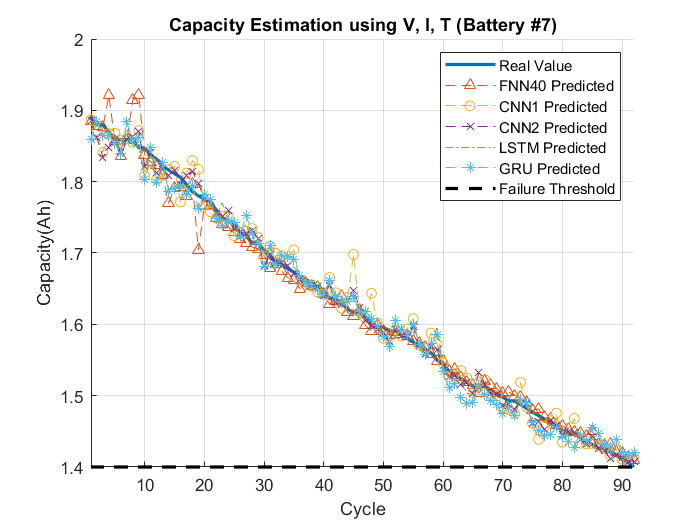

load  netFNN40_07_v1 
load  netCNN1_07_v1 
load  netCNN2_07_v1 
load  netLSTM_07_v1 
load  netGRU_07_v1 

BatteryNum = 7;
pFNN40_07 = netFNN40_07_v1(xB_07');
total_cycle = length(pFNN40_07);
cellx = num2cell(xB_07', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_07 = predict(netCNN1_07_v1, x_4d);
pCNN2_07 = predict(netCNN2_07_v1, x_4d);
pLSTM_07 = cell2mat(predict(netLSTM_07_v1, num2cell(xB_07', 1)));
pGRU_07 = cell2mat(predict(netGRU_07_v1, num2cell(xB_07', 1)));

y_07 = yB_07*yr_07 + ym_07;
pFNN40_07 = pFNN40_07*yr_07 + ym_07;
pCNN1_07 = pCNN1_07*yr_07 + ym_07;
pCNN2_07 = pCNN2_07*yr_07 + ym_07;
pLSTM_07 = pLSTM_07*yr_07 + ym_07;
pGRU_07 = pGRU_07*yr_07 + ym_07;

figure, hold on, grid on,
plot(y_07, 'linewidth', 2), plot(pFNN40_07, '^--'), plot(pCNN1_07, 'o--'), plot(pCNN2_07, 'x--'), plot(pLSTM_07, '-.'),plot(pGRU_07, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_07 = sqrt(mean(( y_07' - pFNN40_07' ).^2))

rmse_pFNN40_07 = 0.0166

rmse_pCNN1_07  = sqrt(mean(( y_07' - pCNN1_07 ).^2))

rmse_pCNN1_07 = single
0.0182

rmse_pCNN2_07  = sqrt(mean(( y_07' - pCNN2_07 ).^2))

rmse_pCNN2_07 = single
0.0114

rmse_pLSTM_07  = sqrt(mean(( y_07' - pLSTM_07 ).^2))

rmse_pLSTM_07 = single
0.0115

rmse_pGRU_07   = sqrt(mean(( y_07' - pGRU_07  ).^2))

rmse_pGRU_07 = single
0.0162


rmse_pFNN40_07

rmse_pFNN40_07 = 0.0166

rmse_pCNN1_07 

rmse_pCNN1_07 = single
0.0182

rmse_pCNN2_07 

rmse_pCNN2_07 = single
0.0114

rmse_pLSTM_07 

rmse_pLSTM_07 = single
0.0115

rmse_pGRU_07  

rmse_pGRU_07 = single
0.0162

### Prediciton #56 by model #5 - Full Data

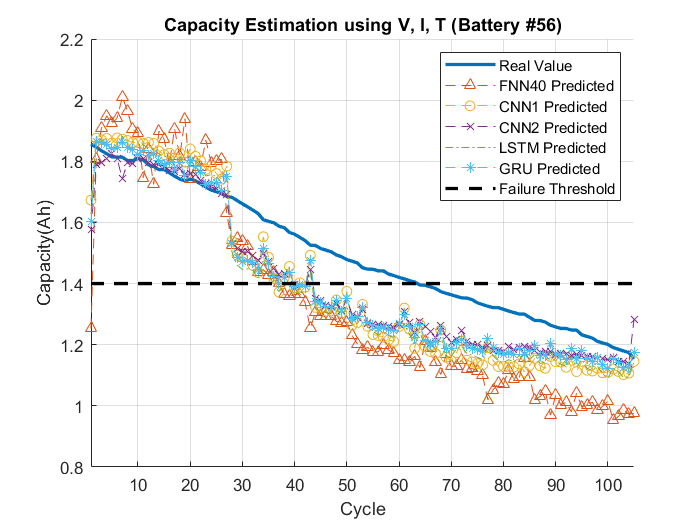

load  netFNN40_05_v1 
load  netCNN1_05_v1 
load  netCNN2_05_v1 
load  netLSTM_05_v1 
load  netGRU_05_v1 

BatteryNum = 56;
pFNN40_0506 = netFNN40_05_v1(xB_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(xB_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05_v1, x_4d);
pCNN2_0506 = predict(netCNN2_05_v1, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05_v1, num2cell(xB_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05_v1, num2cell(xB_0506', 1)));

y_0506 = yB_0506 *yr_0506 + ym_0506 ;
pFNN40_0506 = pFNN40_0506 *yr_0506 + ym_0506 ;
pCNN1_0506 = pCNN1_0506 *yr_0506 + ym_0506 ;
pCNN2_0506 = pCNN2_0506 *yr_0506 + ym_0506 ;
pLSTM_0506 = pLSTM_0506 *yr_0506 + ym_0506 ;
pGRU_0506 = pGRU_0506 *yr_0506 + ym_0506 ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))

rmse_pFNN40_0506 = 0.2091

rmse_pCNN1_0506  = sqrt(mean(( y_0506' - pCNN1_0506 ).^2))

rmse_pCNN1_0506 = single
0.1443

rmse_pCNN2_0506  = sqrt(mean(( y_0506' - pCNN2_0506 ).^2))

rmse_pCNN2_0506 = single
0.1182

rmse_pLSTM_0506  = sqrt(mean(( y_0506' - pLSTM_0506 ).^2))

rmse_pLSTM_0506 = single
0.1467

rmse_pGRU_0506   = sqrt(mean(( y_0506' - pGRU_0506  ).^2))

rmse_pGRU_0506 = single
0.1260


rmse_pFNN40_0506

rmse_pFNN40_0506 = 0.2091

rmse_pCNN1_0506

rmse_pCNN1_0506 = single
0.1443

rmse_pCNN2_0506

rmse_pCNN2_0506 = single
0.1182

rmse_pLSTM_0506

rmse_pLSTM_0506 = single
0.1467

rmse_pGRU_0506

rmse_pGRU_0506 = single
0.1260

### Prediciton #56 by model #5 - From Pattern Change - 시작값이 이상하다.

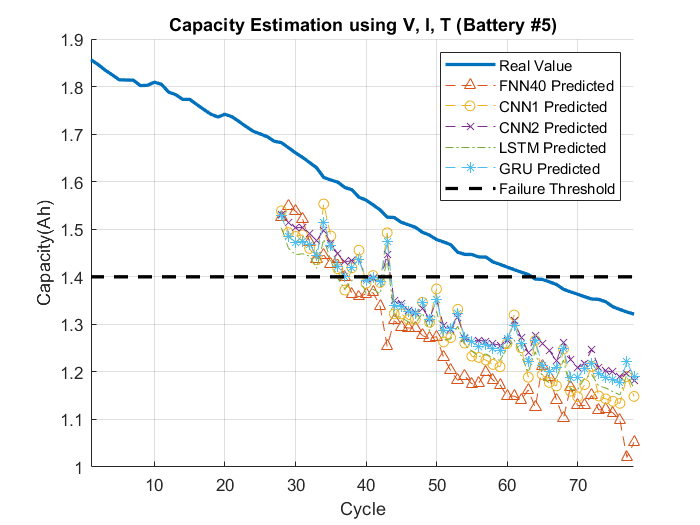



load xB_0506 yB_0506 ym_0506 yr_0506
load xB_0605 yB_0605 ym_0605 yr_0605

load data_0506_patten_change
load data_0605_patten_change

load idx_0506        
load xB_0506_ptn     
load yB_0506_ptn     
load yB_0506_ptn_pre 
load idx_0605        
load xB_0605_ptn     
load yB_0605_ptn     
load yB_0605_ptn_pre 


BatteryNum = 56;

load  netFNN40_05_v1 
load  netCNN1_05_v1 
load  netCNN2_05_v1 
load  netLSTM_05_v1 
load  netGRU_05_v1 

pFNN40_0506 = netFNN40_05_v1(xB_0506_ptn');   
total_cycle = length(pFNN40_0506);
cellx = num2cell(xB_0506_ptn', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05_v1, x_4d);
pCNN2_0506 = predict(netCNN2_05_v1, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05_v1, num2cell(xB_0506_ptn', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05_v1, num2cell(xB_0506_ptn', 1)));

y_0506 = yB_0506 *yr_0506 + ym_0506 ;
y_0506_pre = y_0506(idx_0506:end);
pFNN40_0506_pre = pFNN40_0506 *yr_0506 + ym_0506 ; pFNN40_0506 = [yB_0506_ptn_pre pFNN40_0506_pre];
pCNN1_0506_pre = pCNN1_0506 *yr_0506 + ym_0506 ;   pCNN1_0506 = [yB_0506_ptn_pre' ; pCNN1_0506_pre];
pCNN2_0506_pre = pCNN2_0506 *yr_0506 + ym_0506 ;   pCNN2_0506 = [yB_0506_ptn_pre' ; pCNN2_0506_pre];
pLSTM_0506_pre = pLSTM_0506 *yr_0506 + ym_0506 ;   pLSTM_0506 = [yB_0506_ptn_pre' ; pLSTM_0506_pre];
pGRU_0506_pre = pGRU_0506 *yr_0506 + ym_0506 ;     pGRU_0506 = [yB_0506_ptn_pre' ; pGRU_0506_pre];

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')


rmse_pFNN40_0506 = sqrt(mean(( y_0506_pre(1:length(pFNN40_0506_pre'))' - pFNN40_0506_pre' ).^2))

rmse_pFNN40_0506 = 0.2243

rmse_pCNN1_0506  = sqrt(mean(( y_0506_pre' - pCNN1_0506_pre ).^2))

rmse_pCNN1_0506 = single
0.1618

rmse_pCNN2_0506  = sqrt(mean(( y_0506_pre' - pCNN2_0506_pre ).^2))

rmse_pCNN2_0506 = single
0.1328

rmse_pLSTM_0506  = sqrt(mean(( y_0506_pre' - pLSTM_0506_pre ).^2))

rmse_pLSTM_0506 = single
0.1657

rmse_pGRU_0506   = sqrt(mean(( y_0506_pre' - pGRU_0506_pre  ).^2))

rmse_pGRU_0506 = single
0.1420


rmse_pFNN40_0506

rmse_pFNN40_0506 = 0.2243

rmse_pCNN1_0506

rmse_pCNN1_0506 = single
0.1618

rmse_pCNN2_0506

rmse_pCNN2_0506 = single
0.1328

rmse_pLSTM_0506

rmse_pLSTM_0506 = single
0.1657

rmse_pGRU_0506

rmse_pGRU_0506 = single
0.1420

### Prediciton #56 by model #6 - Full Data

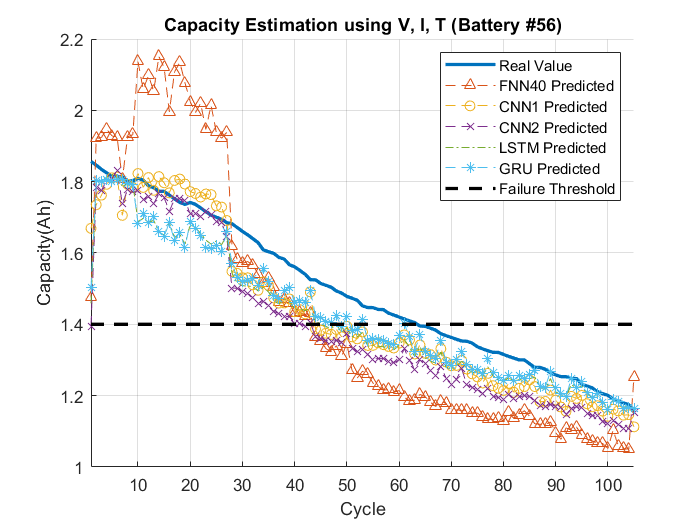

load  netFNN40_06_v1 
load  netCNN1_06_v1 
load  netCNN2_06_v1 
load  netLSTM_06_v1 
load  netGRU_06_v1 


BatteryNum = 56;
pFNN40_0506 = netFNN40_06_v1(xB_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(xB_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_06_v1, x_4d);
pCNN2_0506 = predict(netCNN2_06_v1, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_06_v1, num2cell(xB_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_06_v1, num2cell(xB_0506', 1)));

y_0506 = yB_0506 *yr_0506 + ym_0506 ;
pFNN40_0506 = pFNN40_0506 *yr_0506 + ym_0506 ;
pCNN1_0506 = pCNN1_0506 *yr_0506 + ym_0506 ;
pCNN2_0506 = pCNN2_0506 *yr_0506 + ym_0506 ;
pLSTM_0506 = pLSTM_0506 *yr_0506 + ym_0506 ;
pGRU_0506 = pGRU_0506 *yr_0506 + ym_0506 ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))

rmse_pFNN40_0506 = 0.1934

rmse_pCNN1_0506  = sqrt(mean(( y_0506' - pCNN1_0506 ).^2))

rmse_pCNN1_0506 = single
0.0828

rmse_pCNN2_0506  = sqrt(mean(( y_0506' - pCNN2_0506 ).^2))

rmse_pCNN2_0506 = single
0.1160

rmse_pLSTM_0506  = sqrt(mean(( y_0506' - pLSTM_0506 ).^2))

rmse_pLSTM_0506 = single
0.0920

rmse_pGRU_0506   = sqrt(mean(( y_0506' - pGRU_0506  ).^2))

rmse_pGRU_0506 = single
0.0805

rmse_pFNN40_0506

rmse_pFNN40_0506 = 0.1934

rmse_pCNN1_0506

rmse_pCNN1_0506 = single
0.0828

rmse_pCNN2_0506

rmse_pCNN2_0506 = single
0.1160

rmse_pLSTM_0506

rmse_pLSTM_0506 = single
0.0920

rmse_pGRU_0506

rmse_pGRU_0506 = single
0.0805

### Prediciton #56 by model #7 - Full Data

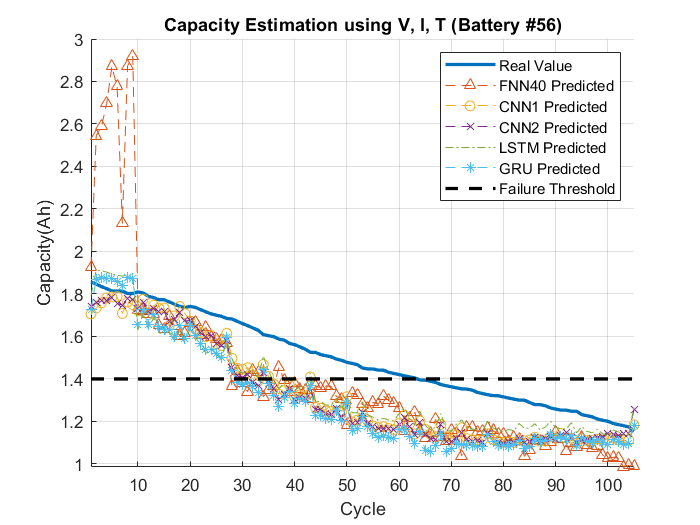

load  netFNN40_07_v1 
load  netCNN1_07_v1 
load  netCNN2_07_v1 
load  netLSTM_07_v1 
load  netGRU_07_v1 


BatteryNum = 56;
pFNN40_0506 = netFNN40_07_v1(xB_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(xB_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_07_v1, x_4d);
pCNN2_0506 = predict(netCNN2_07_v1, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_07_v1, num2cell(xB_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_07_v1, num2cell(xB_0506', 1)));

y_0506 = yB_0506 *yr_0506 + ym_0506 ;
pFNN40_0506 = pFNN40_0506 *yr_0506 + ym_0506 ;
pCNN1_0506 = pCNN1_0506 *yr_0506 + ym_0506 ;
pCNN2_0506 = pCNN2_0506 *yr_0506 + ym_0506 ;
pLSTM_0506 = pLSTM_0506 *yr_0506 + ym_0506 ;
pGRU_0506 = pGRU_0506 *yr_0506 + ym_0506 ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))

rmse_pFNN40_0506 = 0.3016

rmse_pCNN1_0506  = sqrt(mean(( y_0506' - pCNN1_0506 ).^2))

rmse_pCNN1_0506 = single
0.1800

rmse_pCNN2_0506  = sqrt(mean(( y_0506' - pCNN2_0506 ).^2))

rmse_pCNN2_0506 = single
0.1880

rmse_pLSTM_0506  = sqrt(mean(( y_0506' - pLSTM_0506 ).^2))

rmse_pLSTM_0506 = single
0.1613

rmse_pGRU_0506   = sqrt(mean(( y_0506' - pGRU_0506  ).^2))

rmse_pGRU_0506 = single
0.2133

rmse_pFNN40_0506

rmse_pFNN40_0506 = 0.3016

rmse_pCNN1_0506

rmse_pCNN1_0506 = single
0.1800

rmse_pCNN2_0506

rmse_pCNN2_0506 = single
0.1880

rmse_pLSTM_0506

rmse_pLSTM_0506 = single
0.1613

rmse_pGRU_0506

rmse_pGRU_0506 = single
0.2133

### Prediciton #56 by model #5+#6 - Full Data

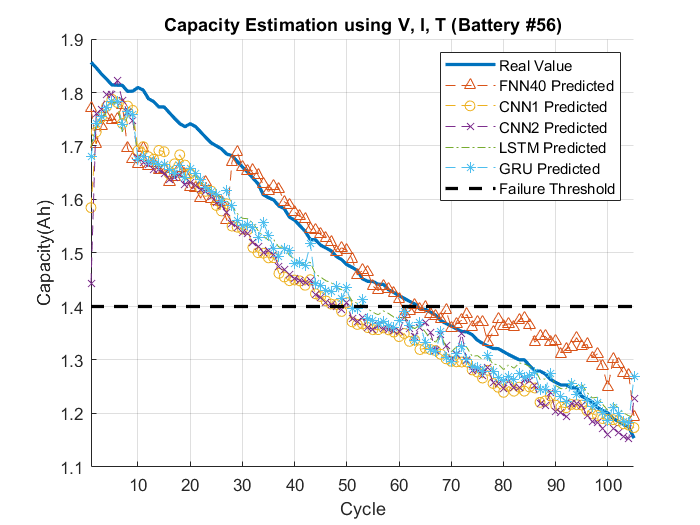

load  netFNN40_05plus06_v1 
load  netCNN1_05plus06_v1 
load  netCNN2_05plus06_v1 
load  netLSTM_05plus06_v1 
load  netGRU_05plus06_v1 

BatteryNum = 56;
pFNN40_0506 = netFNN40_05plus06_v1(xB_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(xB_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05plus06_v1, x_4d);
pCNN2_0506 = predict(netCNN2_05plus06_v1, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05plus06_v1, num2cell(xB_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05plus06_v1, num2cell(xB_0506', 1)));

y_0506 = yB_0506 *yr_0506 + ym_0506 ;
pFNN40_0506 = pFNN40_0506 *yr_0506 + ym_0506 ;
pCNN1_0506 = pCNN1_0506 *yr_0506 + ym_0506 ;
pCNN2_0506 = pCNN2_0506 *yr_0506 + ym_0506 ;
pLSTM_0506 = pLSTM_0506 *yr_0506 + ym_0506 ;
pGRU_0506 = pGRU_0506 *yr_0506 + ym_0506 ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))

rmse_pFNN40_0506 = 0.0682

rmse_pCNN1_0506  = sqrt(mean(( y_0506' - pCNN1_0506 ).^2))

rmse_pCNN1_0506 = single
0.0844

rmse_pCNN2_0506  = sqrt(mean(( y_0506' - pCNN2_0506 ).^2))

rmse_pCNN2_0506 = single
0.0896

rmse_pLSTM_0506  = sqrt(mean(( y_0506' - pLSTM_0506 ).^2))

rmse_pLSTM_0506 = single
0.0647

rmse_pGRU_0506   = sqrt(mean(( y_0506' - pGRU_0506  ).^2))

rmse_pGRU_0506 = single
0.0696

rmse_pFNN40_0506

rmse_pFNN40_0506 = 0.0682

rmse_pCNN1_0506

rmse_pCNN1_0506 = single
0.0844

rmse_pCNN2_0506

rmse_pCNN2_0506 = single
0.0896

rmse_pLSTM_0506

rmse_pLSTM_0506 = single
0.0647

rmse_pGRU_0506

rmse_pGRU_0506 = single
0.0696

### Prediciton #56 by model #5+#6+#7 - Full Data

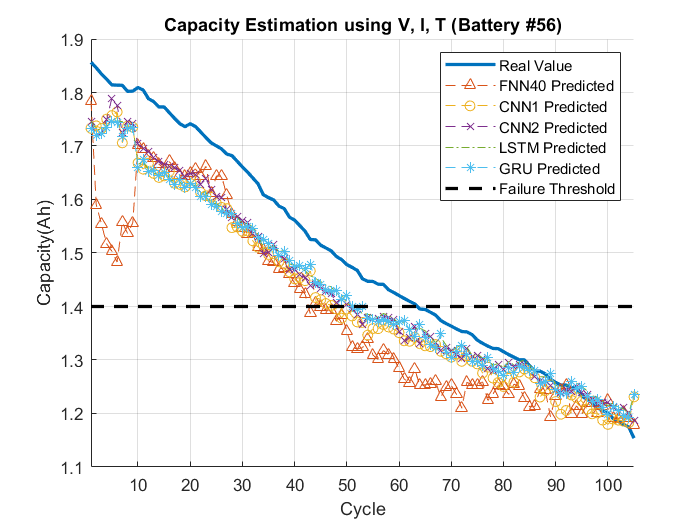

load  netFNN40_05plus06plus07_v1 
load  netCNN1_05plus06plus07_v1 
load  netCNN2_05plus06plus07_v1 
load  netLSTM_05plus06plus07_v1 
load  netGRU_05plus06plus07_v1 

BatteryNum = 56;
pFNN40_0506 = netFNN40_05plus06plus07_v1(xB_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(xB_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05plus06plus07_v1, x_4d);
pCNN2_0506 = predict(netCNN2_05plus06plus07_v1, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05plus06plus07_v1, num2cell(xB_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05plus06plus07_v1, num2cell(xB_0506', 1)));

y_0506 = yB_0506 *yr_0506 + ym_0506 ;
pFNN40_0506 = pFNN40_0506 *yr_0506 + ym_0506 ;
pCNN1_0506 = pCNN1_0506 *yr_0506 + ym_0506 ;
pCNN2_0506 = pCNN2_0506 *yr_0506 + ym_0506 ;
pLSTM_0506 = pLSTM_0506 *yr_0506 + ym_0506 ;
pGRU_0506 = pGRU_0506 *yr_0506 + ym_0506 ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))

rmse_pFNN40_0506 = 0.1232

rmse_pCNN1_0506  = sqrt(mean(( y_0506' - pCNN1_0506 ).^2))

rmse_pCNN1_0506 = single
0.0836

rmse_pCNN2_0506  = sqrt(mean(( y_0506' - pCNN2_0506 ).^2))

rmse_pCNN2_0506 = single
0.0707

rmse_pLSTM_0506  = sqrt(mean(( y_0506' - pLSTM_0506 ).^2))

rmse_pLSTM_0506 = single
0.0733

rmse_pGRU_0506   = sqrt(mean(( y_0506' - pGRU_0506  ).^2))

rmse_pGRU_0506 = single
0.0762

rmse_pFNN40_0506

rmse_pFNN40_0506 = 0.1232

rmse_pCNN1_0506

rmse_pCNN1_0506 = single
0.0836

rmse_pCNN2_0506

rmse_pCNN2_0506 = single
0.0707

rmse_pLSTM_0506

rmse_pLSTM_0506 = single
0.0733

rmse_pGRU_0506

rmse_pGRU_0506 = single
0.0762

%%%%%%%%%%%%%%%%%%%%%%%


### Prediciton #65 by model #5 - Full Data

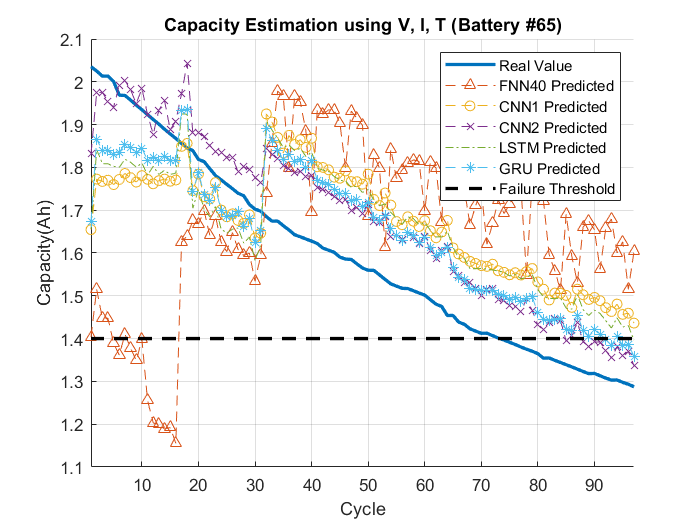

load  netFNN40_05_v1 
load  netCNN1_05_v1 
load  netCNN2_05_v1 
load  netLSTM_05_v1 
load  netGRU_05_v1 

BatteryNum = 65;
pFNN40_0605 = netFNN40_05_v1(xB_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(xB_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_05_v1, x_4d);
pCNN2_0605 = predict(netCNN2_05_v1, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_05_v1, num2cell(xB_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_05_v1, num2cell(xB_0605', 1)));

y_0605 = yB_0605 *yr_0605 + ym_0605 ;
pFNN40_0605 = pFNN40_0605 *yr_0605 + ym_0605 ;
pCNN1_0605 = pCNN1_0605 *yr_0605 + ym_0605 ;
pCNN2_0605 = pCNN2_0605 *yr_0605 + ym_0605 ;
pLSTM_0605 = pLSTM_0605 *yr_0605 + ym_0605 ;
pGRU_0605 = pGRU_0605 *yr_0605 + ym_0605 ;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605(1:length(pFNN40_0605'))' - pFNN40_0605' ).^2))

rmse_pFNN40_0605 = 0.3553

rmse_pCNN1_0605  = sqrt(mean(( y_0605' - pCNN1_0605 ).^2))

rmse_pCNN1_0605 = single
0.1698

rmse_pCNN2_0605  = sqrt(mean(( y_0605' - pCNN2_0605 ).^2))

rmse_pCNN2_0605 = single
0.1024

rmse_pLSTM_0605  = sqrt(mean(( y_0605' - pLSTM_0605 ).^2))

rmse_pLSTM_0605 = single
0.1581

rmse_pGRU_0605   = sqrt(mean(( y_0605' - pGRU_0605  ).^2))

rmse_pGRU_0605 = single
0.1236

rmse_pFNN40_0605

rmse_pFNN40_0605 = 0.3553

rmse_pCNN1_0605

rmse_pCNN1_0605 = single
0.1698

rmse_pCNN2_0605

rmse_pCNN2_0605 = single
0.1024

rmse_pLSTM_0605

rmse_pLSTM_0605 = single
0.1581

rmse_pGRU_0605

rmse_pGRU_0605 = single
0.1236

### Prediciton #65 by model #6 - Full Data

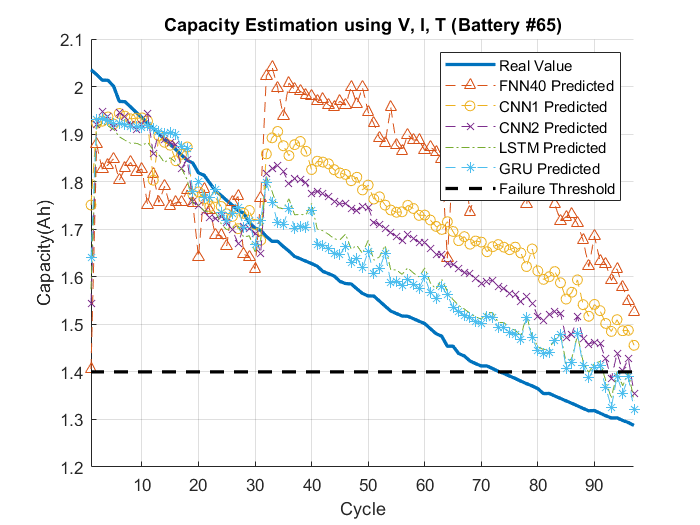

load  netFNN40_06_v1 
load  netCNN1_06_v1 
load  netCNN2_06_v1 
load  netLSTM_06_v1 
load  netGRU_06_v1 

BatteryNum = 65;
pFNN40_0605 = netFNN40_06_v1(xB_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(xB_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_06_v1, x_4d);
pCNN2_0605 = predict(netCNN2_06_v1, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_06_v1, num2cell(xB_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_06_v1, num2cell(xB_0605', 1)));

y_0605 = yB_0605 *yr_0605 + ym_0605 ;
pFNN40_0605 = pFNN40_0605 *yr_0605 + ym_0605 ;
pCNN1_0605 = pCNN1_0605 *yr_0605 + ym_0605 ;
pCNN2_0605 = pCNN2_0605 *yr_0605 + ym_0605 ;
pLSTM_0605 = pLSTM_0605 *yr_0605 + ym_0605 ;
pGRU_0605 = pGRU_0605 *yr_0605 + ym_0605 ;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605(1:length(pFNN40_0605'))' - pFNN40_0605' ).^2))

rmse_pFNN40_0605 = 0.3185

rmse_pCNN1_0605  = sqrt(mean(( y_0605' - pCNN1_0605 ).^2))

rmse_pCNN1_0605 = single
0.1943

rmse_pCNN2_0605  = sqrt(mean(( y_0605' - pCNN2_0605 ).^2))

rmse_pCNN2_0605 = single
0.1450

rmse_pLSTM_0605  = sqrt(mean(( y_0605' - pLSTM_0605 ).^2))

rmse_pLSTM_0605 = single
0.1005

rmse_pGRU_0605   = sqrt(mean(( y_0605' - pGRU_0605  ).^2))

rmse_pGRU_0605 = single
0.0835

rmse_pFNN40_0605

rmse_pFNN40_0605 = 0.3185

rmse_pCNN1_0605

rmse_pCNN1_0605 = single
0.1943

rmse_pCNN2_0605

rmse_pCNN2_0605 = single
0.1450

rmse_pLSTM_0605

rmse_pLSTM_0605 = single
0.1005

rmse_pGRU_0605

rmse_pGRU_0605 = single
0.0835

### Prediciton #65 by model #7 - Full Data

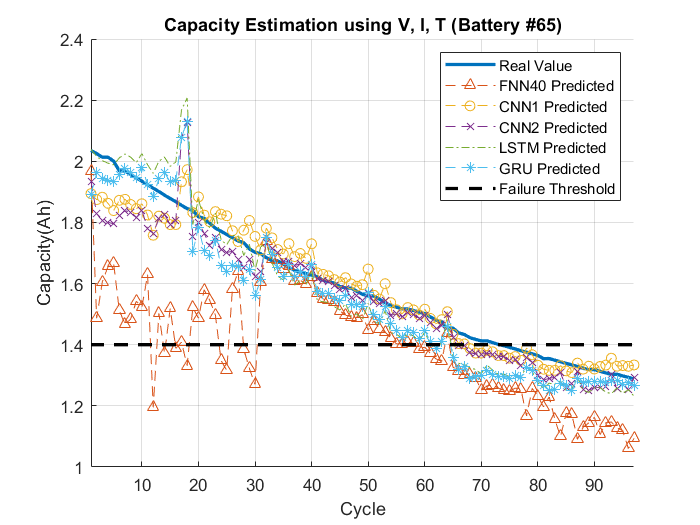

load  netFNN40_07_v1 
load  netCNN1_07_v1 
load  netCNN2_07_v1 
load  netLSTM_07_v1 
load  netGRU_07_v1 

BatteryNum = 65;
pFNN40_0605 = netFNN40_07_v1(xB_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(xB_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_07_v1, x_4d);
pCNN2_0605 = predict(netCNN2_07_v1, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_07_v1, num2cell(xB_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_07_v1, num2cell(xB_0605', 1)));

y_0605 = yB_0605 *yr_0605 + ym_0605 ;
pFNN40_0605 = pFNN40_0605 *yr_0605 + ym_0605 ;
pCNN1_0605 = pCNN1_0605 *yr_0605 + ym_0605 ;
pCNN2_0605 = pCNN2_0605 *yr_0605 + ym_0605 ;
pLSTM_0605 = pLSTM_0605 *yr_0605 + ym_0605 ;
pGRU_0605 = pGRU_0605 *yr_0605 + ym_0605 ;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605(1:length(pFNN40_0605'))' - pFNN40_0605' ).^2))

rmse_pFNN40_0605 = 0.2486

rmse_pCNN1_0605  = sqrt(mean(( y_0605' - pCNN1_0605 ).^2))

rmse_pCNN1_0605 = single
0.0602

rmse_pCNN2_0605  = sqrt(mean(( y_0605' - pCNN2_0605 ).^2))

rmse_pCNN2_0605 = single
0.0778

rmse_pLSTM_0605  = sqrt(mean(( y_0605' - pLSTM_0605 ).^2))

rmse_pLSTM_0605 = single
0.0838

rmse_pGRU_0605   = sqrt(mean(( y_0605' - pGRU_0605  ).^2))

rmse_pGRU_0605 = single
0.0806

rmse_pFNN40_0605

rmse_pFNN40_0605 = 0.2486

rmse_pCNN1_0605

rmse_pCNN1_0605 = single
0.0602

rmse_pCNN2_0605

rmse_pCNN2_0605 = single
0.0778

rmse_pLSTM_0605

rmse_pLSTM_0605 = single
0.0838

rmse_pGRU_0605

rmse_pGRU_0605 = single
0.0806

### Prediciton #65 by model #5+#6 - Full Data

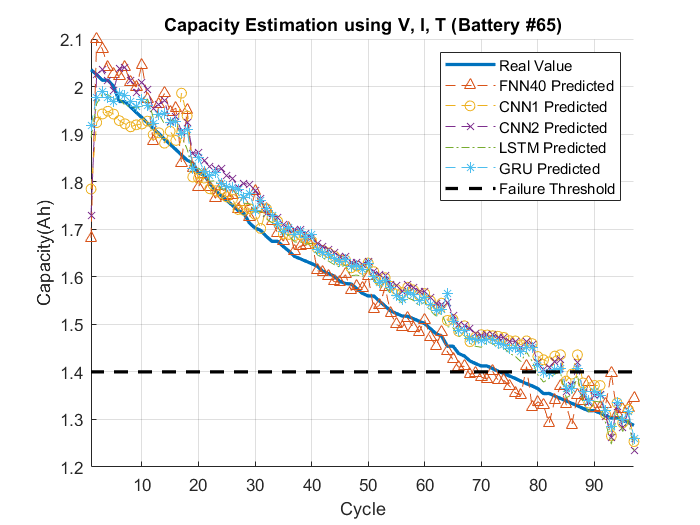

load  netFNN40_05plus06_v1 
load  netCNN1_05plus06_v1 
load  netCNN2_05plus06_v1 
load  netLSTM_05plus06_v1 
load  netGRU_05plus06_v1 

BatteryNum = 65;
pFNN40_0605 = netFNN40_05plus06_v1(xB_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(xB_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_05plus06_v1, x_4d);
pCNN2_0605 = predict(netCNN2_05plus06_v1, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_05plus06_v1, num2cell(xB_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_05plus06_v1, num2cell(xB_0605', 1)));

y_0605 = yB_0605 *yr_0605 + ym_0605 ;
pFNN40_0605 = pFNN40_0605 *yr_0605 + ym_0605 ;
pCNN1_0605 = pCNN1_0605 *yr_0605 + ym_0605 ;
pCNN2_0605 = pCNN2_0605 *yr_0605 + ym_0605 ;
pLSTM_0605 = pLSTM_0605 *yr_0605 + ym_0605 ;
pGRU_0605 = pGRU_0605 *yr_0605 + ym_0605 ;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605(1:length(pFNN40_0605'))' - pFNN40_0605' ).^2))

rmse_pFNN40_0605 = 0.0529

rmse_pCNN1_0605  = sqrt(mean(( y_0605' - pCNN1_0605 ).^2))

rmse_pCNN1_0605 = single
0.0592

rmse_pCNN2_0605  = sqrt(mean(( y_0605' - pCNN2_0605 ).^2))

rmse_pCNN2_0605 = single
0.0656

rmse_pLSTM_0605  = sqrt(mean(( y_0605' - pLSTM_0605 ).^2))

rmse_pLSTM_0605 = single
0.0386

rmse_pGRU_0605   = sqrt(mean(( y_0605' - pGRU_0605  ).^2))

rmse_pGRU_0605 = single
0.0481

rmse_pFNN40_0605

rmse_pFNN40_0605 = 0.0529

rmse_pCNN1_0605

rmse_pCNN1_0605 = single
0.0592

rmse_pCNN2_0605

rmse_pCNN2_0605 = single
0.0656

rmse_pLSTM_0605

rmse_pLSTM_0605 = single
0.0386

rmse_pGRU_0605

rmse_pGRU_0605 = single
0.0481

### Prediciton #65 by model #5+#6+#7 - Full Data

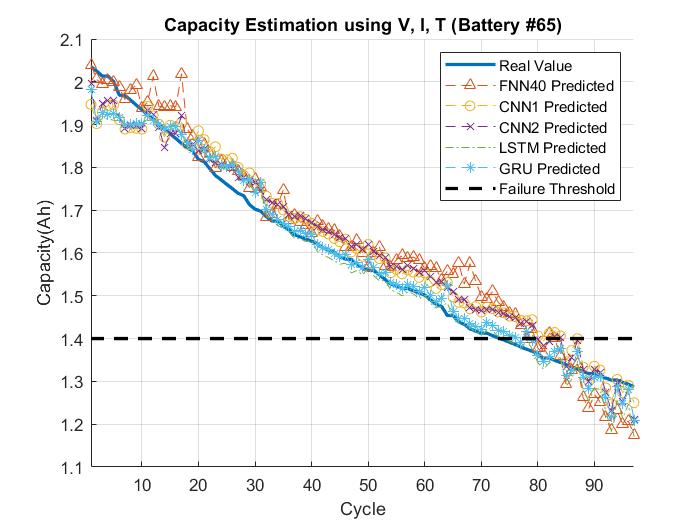

load  netFNN40_05plus06plus07_v1 
load  netCNN1_05plus06plus07_v1 
load  netCNN2_05plus06plus07_v1 
load  netLSTM_05plus06plus07_v1 
load  netGRU_05plus06plus07_v1 


BatteryNum = 65;
pFNN40_0605 = netFNN40_05plus06plus07_v1(xB_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(xB_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_05plus06plus07_v1, x_4d);
pCNN2_0605 = predict(netCNN2_05plus06plus07_v1, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_05plus06plus07_v1, num2cell(xB_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_05plus06plus07_v1, num2cell(xB_0605', 1)));

y_0605 = yB_0605 *yr_0605 + ym_0605 ;
pFNN40_0605 = pFNN40_0605 *yr_0605 + ym_0605 ;
pCNN1_0605 = pCNN1_0605 *yr_0605 + ym_0605 ;
pCNN2_0605 = pCNN2_0605 *yr_0605 + ym_0605 ;
pLSTM_0605 = pLSTM_0605 *yr_0605 + ym_0605 ;
pGRU_0605 = pGRU_0605 *yr_0605 + ym_0605 ;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605(1:length(pFNN40_0605'))' - pFNN40_0605' ).^2))

rmse_pFNN40_0605 = 0.0635

rmse_pCNN1_0605  = sqrt(mean(( y_0605' - pCNN1_0605 ).^2))

rmse_pCNN1_0605 = single
0.0498

rmse_pCNN2_0605  = sqrt(mean(( y_0605' - pCNN2_0605 ).^2))

rmse_pCNN2_0605 = single
0.0477

rmse_pLSTM_0605  = sqrt(mean(( y_0605' - pLSTM_0605 ).^2))

rmse_pLSTM_0605 = single
0.0387

rmse_pGRU_0605   = sqrt(mean(( y_0605' - pGRU_0605  ).^2))

rmse_pGRU_0605 = single
0.0345

rmse_pFNN40_0605

rmse_pFNN40_0605 = 0.0635

rmse_pCNN1_0605

rmse_pCNN1_0605 = single
0.0498

rmse_pCNN2_0605

rmse_pCNN2_0605 = single
0.0477

rmse_pLSTM_0605

rmse_pLSTM_0605 = single
0.0387

rmse_pGRU_0605

rmse_pGRU_0605 = single
0.0345